# Human Activity Recognition Simulink Model for Fixed-Point Deployment

This example shows how to prepare a Simulink® model that classifies human activity based on sensor signals for code generation and deployment to low-power hardware. The example provides a Simulink classification model that is ready for deployment to a BBC micro:bit device. First, download and install Simulink Coder™ Support Package for BBC micro:bit from the Add-On Explorer. Then, train the classification model and deploy the Simulink model to the target device.

## Load Sample Data Set

Load the `humanactivity` data set.

load humanactivity

The `humanactivity` data set contains 24,075 observations of five physical human activities: Sitting, Standing, Walking, Running, and Dancing. Each observation has 60 features extracted from acceleration data measured by smartphone accelerometer sensors. The data set contains the following variables:

- `actid` — Response vector containing the activity IDs in integers: 1, 2, 3, 4, and 5 representing Sitting, Standing, Walking, Running, and Dancing, respectively

- `actnames` — Activity names corresponding to the integer activity IDs

- `feat` — Feature matrix of 60 features for 24,075 observations

- `featlabels` — Labels of the 60 features

The Sensor HAR (human activity recognition) App [1] was used to create the `humanactivity` data set. When measuring the raw acceleration data with this app, a person placed a smartphone in a pocket so that the smartphone was upside down and the screen faced toward the person. The software then calibrated the measured raw data accordingly and extracted the 60 features from the calibrated data. For details about the calibration and feature extraction, see [2] and [3], respectively. The Simulink models described later also use the raw acceleration data and include blocks for calibration and feature extraction. 

To reduce the memory footprint for fixed-point deployment, specify to use only the first 15 features of the data set in the trained classifier.

feat = feat(:,1:15);
featlabels = featlabels(1:15);

## Prepare Data

This example uses 90% of the observations to train a model that classifies the five types of human activities, and 10% of the observations to validate the trained model. Use [`cvpartition`](docid:stats_ug.brxwayf-1) to specify a 10% holdout for the test set.

rng('default') % For reproducibility
Partition = cvpartition(actid,'Holdout',0.10);

Extract the training and test indices.

trainInds = training(Partition);
testInds = test(Partition);

Specify the training and test data sets.

XTrain = feat(trainInds,:);
YTrain = actid(trainInds);
XTest = feat(testInds,:);
YTest = actid(testInds);

## Train Decision Tree at Command Line

Train a fitted binary classification decision tree using the predictors `XTrain` and class labels `YTrain`. A recommended practice is to specify the class names. Also, specify a maximum of 20 branch nodes for the decision tree.

classificationTree = fitctree(XTrain,YTrain,...
    'ClassNames',[1;2;3;4;5],...
    'MaxNumSplits',20)

Perform 5-fold cross-validation for `classificationTree` and compute the validation accuracy.

partitionedModel = crossval(classificationTree,'KFold',5);
validationAccuracy = 1-kfoldLoss(partitionedModel)

Alternatively, you can train and cross-validate the same classification model using the Classification Learner app. For a similar example, see [Human Activity Recognition Simulink Model for Smartphone Deployment](docid:stats_ug#mw_52ca30ec-978c-4f68-928a-51a19b4e4875).

## Evaluate Performance on Test Data

Determine how well the algorithm generalizes by estimating the test sample classification error.

testAccuracy = 1-loss(classificationTree,XTest,YTest)

The trained model correctly classifies 96.17% of the human activities on the test data set. This result confirms that the trained model does not overfit to the training data set. 

Note that the accuracy values can vary slightly depending on your operating system. 

## Predict in Simulink Model

Now that you have prepared a classification model, you can open the Simulink model. You can import the trained classification object containing the decision tree `classificationTree` into a [**ClassificationTree Predict**](docid:stats_ug#mw_d5dfffe4-12bb-4a68-ab65-00b4f321f2c5) block. You can add this block from the Statistics and Machine Learning Toolbox™ library. For more information on how to create a model that includes a **ClassificationTree Predict** block, see [Predict Class Labels Using ClassificationTree Predict Block](docid:stats_ug#mw_4dfa9b14-e048-4dd6-8208-bf1b6a6f3ce9). In this case, you will use the Simulink model `slexHARFixedPointExample` provided with this example.

Create a large set of accelerometer data `ts` to use as input to the Simulink model.

inData = load('rawAccData');
Xacc = inData.acc_data;
t = 0:size(Xacc,1)-1;
ts = timeseries(Xacc,t,'InterpretSingleRowDataAs3D',true);
numSteps = numel(t)-1;

Open the Simulink model `slexHARFixedPointExample` by entering the following at the command line. Note that the Simulink model includes callbacks that load necessary variables for the preprocessing subsystem into the base workspace.

slexHARFixedPointExample

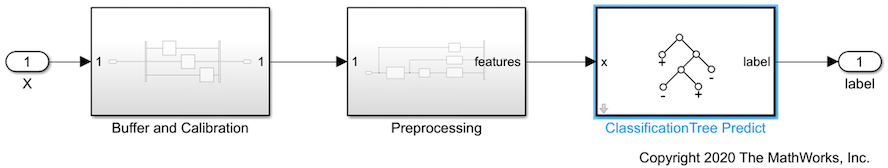

The `slexHARFixedPointExample` model contains the following blocks:

- The **X** block (input port) links the signal `ts` from the Workspace into the system.

- The **Buffer and Calibration** block contains three **Buffer** blocks: **X Buffer**, **Y Buffer**, and **Z Buffer**. Each of these blocks buffers 32 samples of an accelerometer axis with 12 samples of overlap between buffered frames. After collecting 20 samples, each **Buffer** block joins them with 12 samples from the previous frame and passes the total of 32 samples to the **Preprocessing** block. Each **Buffer** block receives an input sample every 0.1 second and outputs a buffered frame including 32 samples every 2 seconds.

- The **Preprocessing** block extracts 15 features from a buffered frame of 32 accelerometer samples. This subsystem block uses DSP System Toolbox™ and Signal Processing Toolbox™.

- The **ClassificationTree Predict** block is a library block from the Statistics and Machine Learning Toolbox library that classifies the human activities using the extracted features. The output is an integer between 1 and 5, corresponding to Sitting, Standing, Walking, Running, and Dancing, respectively.

## Convert to Fixed-Point

Convert the `slexHARFixedPointExample` model to the fixed-point model `slexHARFixedPointConvertedExample`. Then, deploy `slexHARFixedPointConvertedExample` to the BBC micro:bit board. The target device does not have a floating-point unit (FPU), and performs fixed-point calculations more efficiently than floating-point calculations.

In the `slexHARFixedPointExample` model, right-click the **Label** port and select **Log Selected Signals**. Then, open the **Fixed-Point Tool** app by selecting it from the apps gallery, available from the **Apps** tab. In the Fixed-Point Tool, under **New** workflow, select `Iterative Fixed-Point Conversion`.

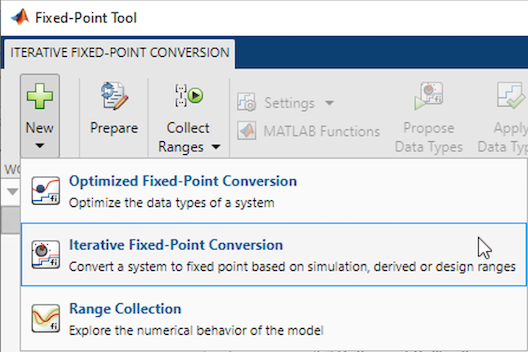

On the **Iterative Fixed-Point Conversion** tab, in the **Signal Tolerances** section, specify the acceptable level of tolerance (difference between the original value and the value of the new design) for the `label` signal. A recommended practice for classification models is to specify 0 absolute tolerance. With this setting, the labels returned by the fixed-point classification model must be the same as the labels returned by the floating-point model. (For regression models, the acceptable tolerance can be a nonzero user-specified number.)

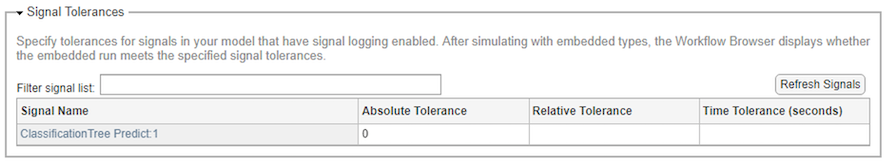

Then, review the steps in the example [Convert Floating-Point Model to Fixed Point](docid:fixedpoint_ug#bsotv83) to learn how to create a Simulink model that is converted to fixed-point.

Open the fixed-point Simulink model `slexHARFixedPointConvertedExample` by entering the following at the command line. The **Subsystem** block contains the **Buffer and Calibration**, **Preprocessing**, and **ClassificationTree Predict** blocks as shown earlier for the `slexHARFixedPointExample` model.

slexHARFixedPointConvertedExample

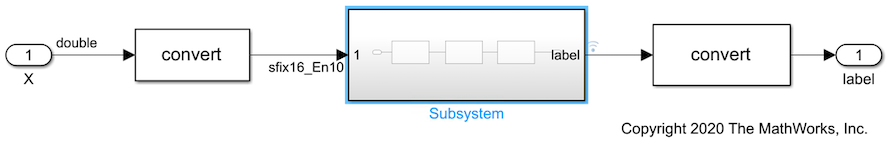

Alternatively, you can select the `Optimized Fixed-Point Conversion` workflow in the **Fixed-Point Tool** app or manually define the data type in the block dialog box. For more information, see [Configure Blocks with Fixed-Point Output](docid:fixedpoint_ug#f25101).

## Deploy to Hardware

Open the Simulink model for deployment to the BBC micro:bit device by entering the following at the command line. The `slexHARFixedPointDeployExample` model is converted to fixed-point, and has I/O blocks for the accelerometer and display ports on the target device.

slexHARFixedPointDeployExample

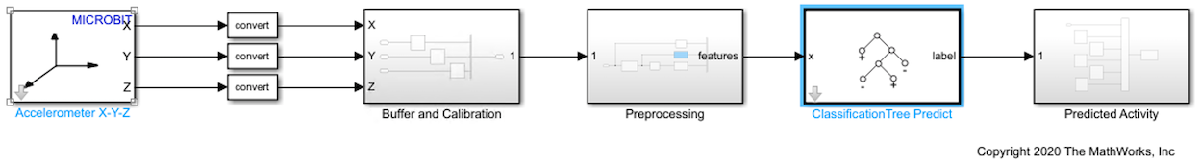

The Simulink model `slexHARFixedPointDeployExample` classifies the human activities based on acceleration data measured by a smartphone sensor. The model includes the following blocks:

- The **Accelerometer** block receives raw acceleration data from accelerometer sensors on the device.

- The **Buffer and Calibration**, **Preprocessing**, and **ClassificationTree Predict** blocks are the same as those shown earlier for the `slexHARFixedPointExample` model.

- The **Predicted Activity** block displays the classified human activity values on the 5x5 LED matrix of the BBC micro:bit device. The letters "S", "T", "W", "R", and "D" represent Sitting, Standing, Walking, Running, and Dancing, respectively.

To deploy the Simulink model to your device, follow the steps in [Getting Started with Simulink Coder Support Package for BBC micro:bit](docid:microbit_ref#mw_bd2bc1b7-5914-4cc0-b290-5bca3ba98114). Run the model on your device, place the device in the same way as described earlier for collecting the training data, and try the five activities. The model displays the classified activity accordingly.

To ensure the accuracy of the model, you must place your device in the same way as described for collecting the training data. If you want to place your device in a different location or at a different orientation, then collect the data in your own way and use your data to train the classification model.    

The accuracy of the model can be different from the accuracy of the test data set (`testAccuracy`), depending on the device. To improve the model accuracy, consider using additional sensors, such as a gyroscope. 

## References

[1] El Helou, Amine. Sensor HAR Recognition App. MathWorks File Exchange [https://www.mathworks.com/matlabcentral/fileexchange/54138-sensor-har-recognition-app](https://www.mathworks.com/matlabcentral/fileexchange/54138-sensor-har-recognition-app)

[2] STMicroelectronics, AN4508 Application note. “Parameters and calibration of a low-g 3-axis accelerometer.” 2014. [https://www.st.com/resource/en/application_note/dm00119044-parameters-and-calibration-of-a-lowg-3axis-accelerometer-stmicroelectronics.pdf](https://www.st.com/resource/en/application_note/dm00119044-parameters-and-calibration-of-a-lowg-3axis-accelerometer-stmicroelectronics.pdf)

[3] El Helou, Amine. Sensor Data Analytics. MathWorks File Exchange [https://www.mathworks.com/matlabcentral/fileexchange/54139-sensor-data-analytics--french-webinar-code-](https://www.mathworks.com/matlabcentral/fileexchange/54139-sensor-data-analytics--french-webinar-code-)

*Copyright 2020 The MathWorks, Inc.*